% simulation parameters
F = 1;
M = 1;
g = 9.808;
L = 0.613;

% travel restrictions
eta_1 = 0.1;
eta_2 = 0.1;
e0 = 0.03;

% initial conditions
s_0 = 0.1;
theta_0 = 0.1;

x1_0 = s_0;
x3_0 = s_0 + L*theta_0;

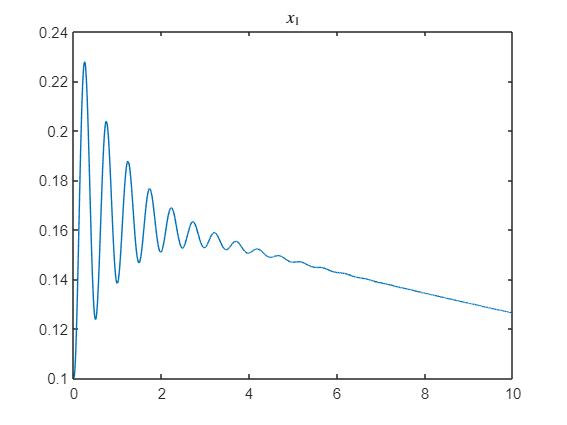

% simulate the pendulum with feedback control (Saberi, 1996)
tspan = 0:0.001:10;

mu = 0.2;
u=@(x) -M/mu * controlLaw(x,g,L,e0);

x0 = [x1_0 0 x3_0 0];
[t,x] = ode45(@(t,x)simpend(x,M,F,g,L,u(x)),tspan,x0);

plot(t,x(:,1)); title('$x_1$','Interpreter','latex')

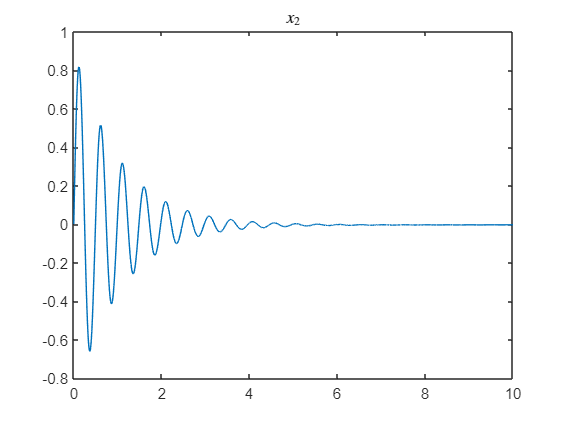

plot(t,x(:,2)); title('$x_2$','Interpreter','latex')

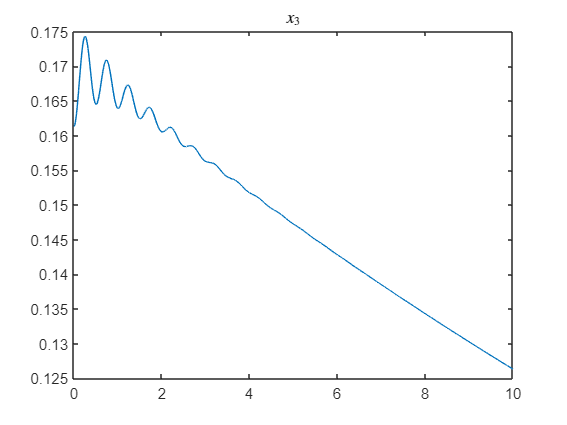

plot(t,x(:,3)); title('$x_3$','Interpreter','latex')

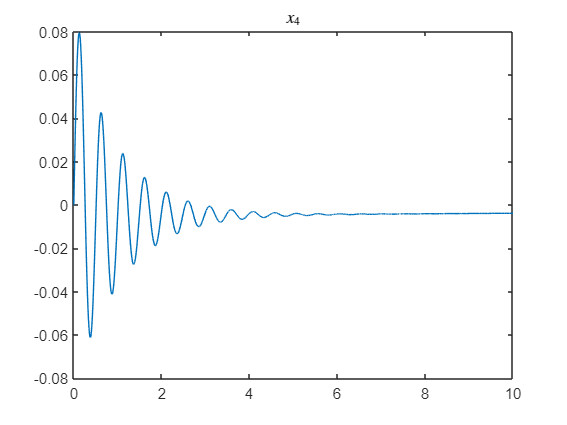

plot(t,x(:,4)); title('$x_4$','Interpreter','latex')

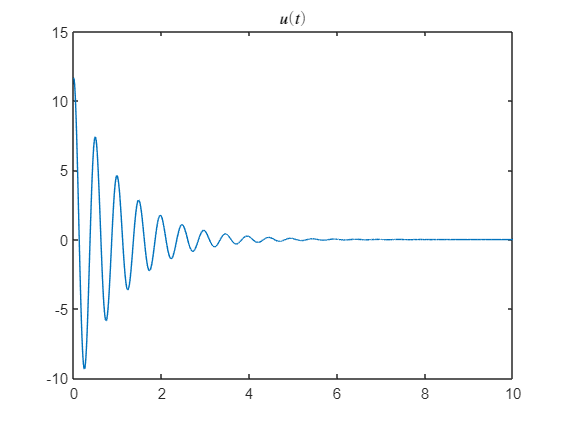

input_sig = zeros(size(t));
for i=1:length(input_sig)
    input_sig(i) = u(x(i,:));
end

plot(t,input_sig); title('$u(t)$','Interpreter','latex')

% % linear state feedback control law
% x = sym('x', [4,1])
% vpa(controlLaw(x,g,L,e0),4)

% % simulate the pendulum with no input
% tspan = 0:0.001:10;
% 
% x0 = [0 0 pi/6 0];
% [t,x] = ode45(@(t,x)simpend(x,M,F,g,L,0),tspan,x0);
% 
% plot(t,rad2deg(x(:,3)))
% title('\theta vs Time')
% grid on
% hold on
% plot(t,ones(size(t))*360);
% ylabel('\theta (deg)')
% xlabel('time (s)')
% hold off

% create a fun animation, save to a video
% fprintf("Creating animation...")
% f = figure('Visible','off');
% v = VideoWriter('InvertedPendulumHighLowGain');
% open(v);
% for k=1:30:length(t)
%     drawpend(x(k,:),L);
%     frame = getframe(gcf);
%     writeVideo(v,frame);
% end
% close(v);
% fprintf("done\n")